clearvars;close all;clc;

**Proměnné:**

syms m_b m_t J_b R l x(t) phi(t) g M_x(t)
x_dot = diff(x,t);
phi_dot = diff(phi,t);
x_ddot = diff(x_dot);
phi_ddot = diff(phi_dot);

**Konstanty:**

consts = [m_b m_t J_b R l g];
values = [2.5 1 12.5 0.16 0.6 9.81];    %[kg kg kg*m^2 m m kg*s^-2kg]

**Kinetická energie **$E_k
$**:**

%Koule
E_kTrans = 1/2*m_b*x_dot^2; %Translační kinetická energie koule
E_kRot = 1/2*J_b*(x_dot/R)^2;   %Rotační kinetická energie koule
E_kB = E_kTrans + E_kRot;   %Celková kinetická energie koule

%Tělo
x_T_dot = x_dot + l*cos(phi)*phi_dot;   %Rychlost těla ve směru x 
y_T_dot = - l*sin(phi)*phi_dot; %Rychlost těla ve směru y
v_t_squared = x_T_dot^2 + y_T_dot^2;    %Celková rychlost

E_kT = 1/2*m_t*v_t_squared; %Kinetická energie Těla

E_k = E_kB + E_kT;

**Potenciální energie **$E_p$**:**

E_p = m_t*g*(R + l*cos(phi));   %Potenciální energie těla (koule žádnou nemá(jede po rovině))

**Lagrangeova rovnice:**


$$\frac{d}{dt} \left( \frac{\partial L}{\partial \dot{q}_i} \right) - \frac{\partial L}{\partial q_i} = Q
$$



$$
L = E_k - E_p$$


L = E_k - E_p;  %Lagrangián

parc_diff_x = simplify(diff(L,x));      %x   Druhý člen Lagrangeovy rovnice
parc_diff_phi = simplify(diff(L,phi));  %phi

parc_diff_x_dot = diff(L,x_dot);        %x      část prvního členu v závorce
parc_diff_phi_dot = diff(L,phi_dot);    %phi

time_diff_x = simplify(diff(parc_diff_x_dot,t));        %x      první člen
time_diff_phi = simplify(diff(parc_diff_phi_dot,t));    %phi    druhý člen

Lagr_1 = time_diff_x - parc_diff_x == M_x;      %Matematický nelineární popis systému
Lagr_2 = time_diff_phi - parc_diff_phi == 0;    %

**Stavový popis:**

$\left\lbrack \begin{array}{c}
x\\
\dot{x} \\
\varphi \\
\dot{\varphi} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\mathbf{x}$        ;        $\dot{\mathbf{x}} =\left\lbrack \begin{array}{c}
\dot{x} \\
\ddot{x} \\
\dot{\varphi} \\
\ddot{\varphi} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_2 \\
\ddot{x} \\
x_4 \\
\ddot{\varphi} 
\end{array}\right\rbrack$

Lagr = [                        %Vektorovy Lagrangeovsky popis systemu
    lhs(Lagr_1) - rhs(Lagr_1);
    lhs(Lagr_2) - rhs(Lagr_2)
    ];

syms ddx ddphi

Lagr = subs(Lagr,[x_ddot phi_ddot],[ddx ddphi]);    %Kvuli solve() symbolicke promenne

sol = solve(Lagr,[ddx, ddphi]); 

disp('x_ddot =');disp(' ');pretty(simplify(sol.ddx));

x_ddot =
 
 2 /                   /  d        \2                                          \
R  | l m_t sin(phi(t)) | -- phi(t) |  + M_x(t) - g m_t cos(phi(t)) sin(phi(t)) |
   \                   \ dt        /                                           /
--------------------------------------------------------------------------------
                          2        2        2                2
                   J_b + R  m_b + R  m_t - R  m_t cos(phi(t))



disp('phi_ddot =');disp(' ');pretty(simplify(sol.ddphi));

phi_ddot =
 
                     2                       2                      2                      2                               /  d        \2
J_b g sin(phi(t)) - R  cos(phi(t)) M_x(t) + R  g m_b sin(phi(t)) + R  g m_t sin(phi(t)) - R  l m_t cos(phi(t)) sin(phi(t)) | -- phi(t) |
                                                                                                                           \ dt        /
-----------------------------------------------------------------------------------------------------------------------------------------
                                                       2        2        2                2
                                             l (J_b + R  m_b + R  m_t - R  m_t cos(phi(t)) )




syms x1 x2 x3 x4 u  %Stavové proměnné

sol = subs(sol, [x x_dot phi phi_dot M_x], [x1 x2 x3 x4 u]);    %Dosadí stavové proměnné

F = [      %Stavový vektorový popis (rovnice pravých stran)
    x2;
    sol.ddx;
    x4;
    sol.ddphi
    ]

$$F = \left(\begin{array}{c} x_{2}\\ \frac{R^{2}\,\left(u-g\,m_{t}\,\cos\left(x_{3}\right)\,\sin\left(x_{3}\right)\right)}{J_{b}+R^{2}\,m_{b}+R^{2}\,m_{t}-R^{2}\,m_{t}\,{\cos\left(x_{3}\right)}^{2}}\\ x_{4}\\ \frac{J_{b}\,g\,\sin\left(x_{3}\right)-R^{2}\,u\,\cos\left(x_{3}\right)+R^{2}\,g\,m_{b}\,\sin\left(x_{3}\right)+R^{2}\,g\,m_{t}\,\sin\left(x_{3}\right)}{l\,\left(J_{b}+R^{2}\,m_{b}+R^{2}\,m_{t}-R^{2}\,m_{t}\,{\cos\left(x_{3}\right)}^{2}\right)} \end{array}\right)$$



F_nl = subs(F, [x1 x2 x3 x4 u], [x x_dot phi phi_dot M_x]); % F ve fyzikálních proměnných

num_F = vpa(subs(F, consts, values));    %Vyčíslené rovnice pravých stran

symvars = symvar(num_F);    %Zjištění symbolických proměnných
assume(symvars,'real')      %Pouze realné hodnoty
sol = solve(num_F==0);       %Najití singulárních bodů systému


disp('Singulární bod 1:');disp('        u  x2  x3  x4');disp('        Nm  m  °  rad/s');s_p1 = [sol.u(1) sol.x2(1) vpa(rad2deg(sol.x3(1))) sol.x4(1)]

Singulární bod 1:
        u  x2  x3  x4
        Nm  m  °  rad/s


$$s\_p1 = \left(\begin{array}{cccc} 0 & 0 & 180.0 & 0 \end{array}\right)$$

disp('Singulární bod 2:');disp('        u  x2  x3  x4');disp('        Nm  m  °  rad/s');s_p2 = [sol.u(2) sol.x2(2) vpa(rad2deg(sol.x3(2))) sol.x4(2)]

Singulární bod 2:
        u  x2  x3  x4
        Nm  m  °  rad/s


$$s\_p2 = \left(\begin{array}{cccc} 0 & 0 & 0 & 0 \end{array}\right)$$

Systém má dva singulární body "**když je tělo nahoře**" a "**když je tělo dole**"

Vzhledem k funkci robota bude systém linearizován v **singulárním bodě 2**, neboli když je tělo nahoře

**Linearizace:**

%Matice A
xx = [x1 x2 x3 x4];      %Stavové proměnné
J_A_sym = jacobian(F,xx);    %Symbolická Jacobyho matice pro A
J_A = jacobian(num_F,xx);    %Numerická Jacobyho matice pro A
A_sym = subs(J_A_sym, [u x2 x3 x4], s_p2)   %Symbolická matice dynamiky (doplnění singulárního bodu 2)

$$A\_sym = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & -\frac{R^{2}\,g\,m_{t}}{m_{b}\,R^{2}+J_{b}} & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & \frac{J_{b}\,g+R^{2}\,g\,m_{b}+R^{2}\,g\,m_{t}}{l\,\left(m_{b}\,R^{2}+J_{b}\right)} & 0 \end{array}\right)$$

A = double(subs(J_A, [u x2 x3 x4], s_p2))    %Numerická matice dynamiky (doplnění singulárního bodu 2)

A =          0    1.0000         0         0
         0         0   -0.0200         0
         0         0         0    1.0000
         0         0   16.3833         0



%Matice B
J_B_sym = jacobian(F,u);    %Symbolická Jacobyho matice pro B
J_B = jacobian(num_F,u);   %Numerická Jacobyho matice pro B
B_sym = subs(J_B_sym, [u x2 x3 x4], s_p2)   %Symbolická matice B (doplnění singulárního bodu 2)

$$B\_sym = \left(\begin{array}{c} 0\\ \frac{R^{2}}{m_{b}\,R^{2}+J_{b}}\\ 0\\ -\frac{R^{2}}{l\,\left(m_{b}\,R^{2}+J_{b}\right)} \end{array}\right)$$

B = double(subs(J_B, [u x2 x3 x4], s_p2))    %Numerická matice B (doplnění singulárního bodu 2)

B =          0
    0.0020
         0
   -0.0034



%Matice C
C = [               %Výstupy jsou poloha
    1 0 0 0;
    0 0 180/pi 0
    ]

C =     1.0000         0         0         0
         0         0   57.2958         0



%matice D
D = [0;0]

D =      0
     0


**Linearizovaný SS model:**

sys = ss(A,B,C,D)

sys =
 
  A = 
             x1        x2        x3        x4
   x1         0         1         0         0
   x2         0         0  -0.01999         0
   x3         0         0         0         1
   x4         0         0     16.38         0
 
  B = 
              u1
   x1          0
   x2   0.002038
   x3          0
   x4  -0.003396
 
  C = 
         x1    x2    x3    x4
   y1     1     0     0     0
   y2     0     0  57.3     0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


syms s
eig(A)  %3. kořen nestabilní -> systém je nestabilní

ans =          0
         0
    4.0476
   -4.0476


        %0 imaginární složka -> nekmitavý systém

**Nelineární model:**

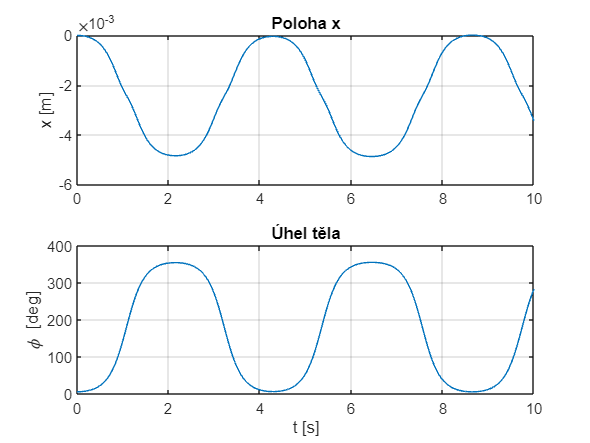

f_nl = matlabFunction(num_F, 'Vars', {x1, x2, x3, x4, u});  
% f_nl(X, M_x) kde X = [x; x_dot; phi; phi_dot]
u_fun = @(t) 0;
odefun = @(t, X) f_nl(X(1), X(2), X(3), X(4), u_fun(t));

x0 = [0; 0; 0.1; 0];   % počáteční podmínky
tspan = [0 10];

[t, X] = ode45(odefun, tspan, x0);


figure;
subplot(2,1,1)
plot(t, X(:,1)); ylabel('x [m]'); grid on; title('Poloha x');
subplot(2,1,2)
plot(t, rad2deg(X(:,3))); ylabel('\phi [deg]'); grid on; title('Úhel těla');
xlabel('t [s]')

**MPC (MATLAB):**

Ts = 0.05;  % vzorkovací doba (ms)
p = 20;     % predikční horizont
m = 10;     % horizont řízení

mpcobj = mpc(sys, Ts, p, m);

'mpc' requires Model Predictive Control Toolbox.


%Omezení
mpcobj.MV.Min = -1;
mpcobj.MV.Max = 1;

mpcobj.OV(1).Min = -0.5;   % omezení pro x
mpcobj.OV(1).Max = 0.5;

mpcobj.OV(2).Min = deg2rad(-10);  % omezení pro phi
mpcobj.OV(2).Max = deg2rad(10);